Image from 2000

yr2000 = imread("2000.jpg");
% imshow(yr2000)
% title("Year 2000")

Image from 2017

yr2017 = imread("2017.jpg");
% imshow(yr2017)
% title("Year 2017")

Compare the two images

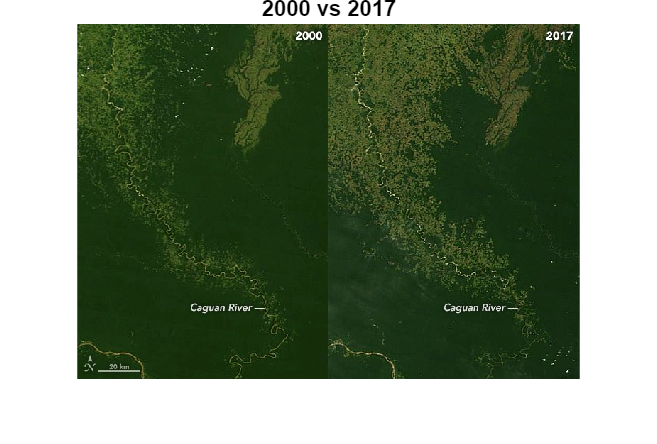

imshowpair(yr2000, yr2017, "montage")
title("2000 vs 2017")

Convert to grayscale

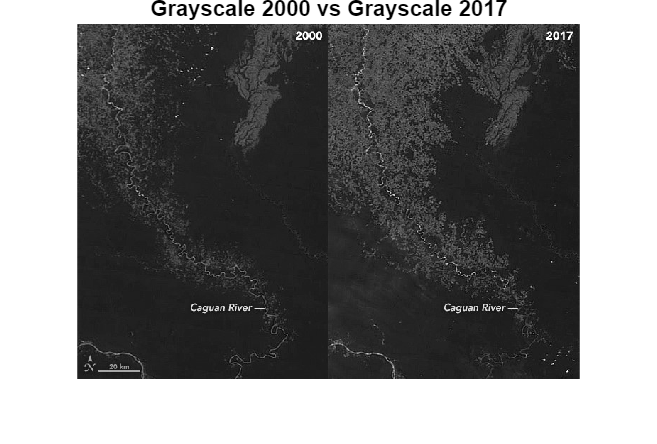

gray2000 = im2gray(yr2000);
gray2017 = im2gray(yr2017);
imshowpair(gray2000, gray2017, "montage")
title("Grayscale 2000 vs Grayscale 2017")

Analyze histogram for segmentation

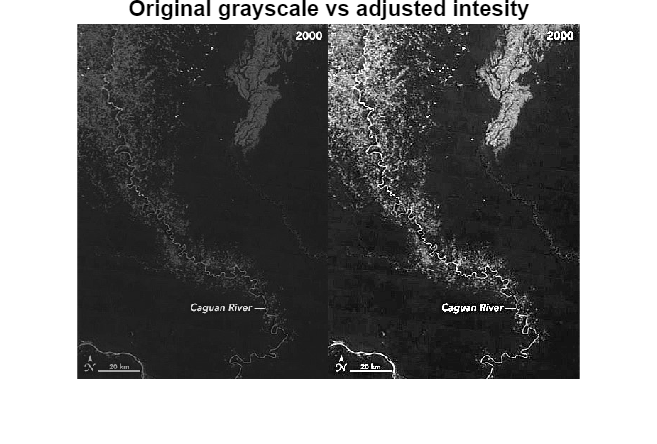

% imhist(gray2000)
% title("grayscale histogram")
adj2000 = imadjust(gray2000);
imshowpair(gray2000, adj2000, "montage")
title("Original grayscale vs adjusted intesity")

Use image segmenter app to find desired region to segment

For better results, we can segment based on color to avoid false segmentation that may include clouds and overlay text

USE color thresholder app

Color segmented outputs

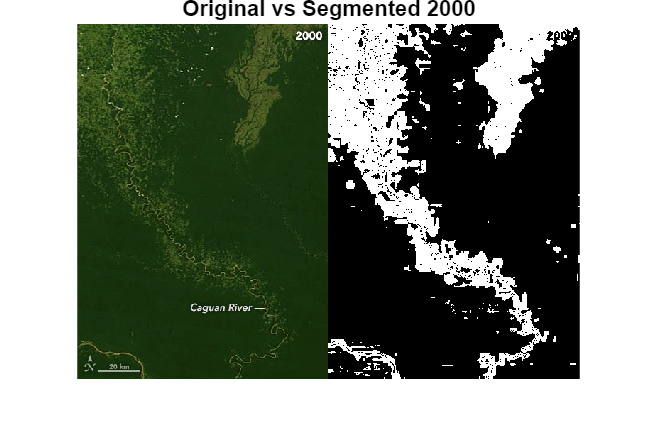

bi2000 = createMask(yr2000);
bi2017 = createMask(yr2017);
imshowpair(yr2000, bi2000, "montage")
title("Original vs Segmented 2000")

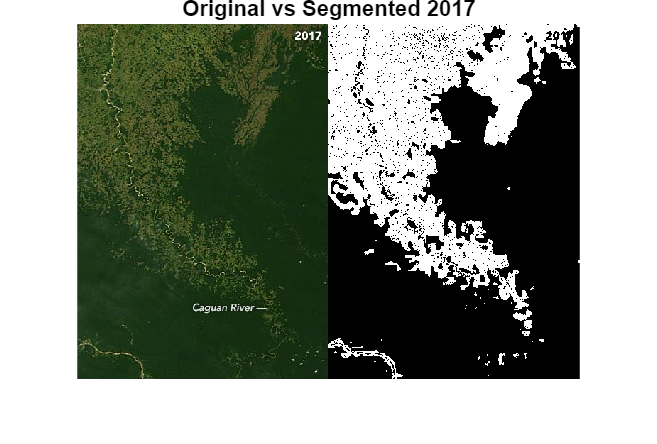

imshowpair(yr2017, bi2017, "montage")
title("Original vs Segmented 2017")

Calculate area of deforested (segmented) region

props2000 = regionprops("table", bi2000, "Area")

props2000 = 137×1 table
    Area 
    _____

    31960
      156
     1149
       28
       35
        6
        4
       26
        4
        8
        2
        1
      132
        7
        9
        2


areaPx2000 = sum(props2000.Area)

areaPx2000 = 46739

props2017 = regionprops("table", bi2017, "Area")

props2017 = 57×1 table
    Area 
    _____

    60311
      803
        7
        6
       21
       70
        8
        7
        8
      105
        6
        1
        9
        3
        1
        4


areaPx2017 = sum(props2017.Area)

areaPx2017 = 63440

To convert to actual area in km^2, we can use Image Viewer app, and convert given scale to km.

20 km = 58 px

1 px = 20/58 kms

area of 1 px = (20/58)^2 km^2

px2km = (20/58)^2

px2km = 0.1189

area2000 = round(areaPx2000*px2km)

area2000 = 5558

area2017 = round(areaPx2017*px2km)

area2017 = 7543